## Reading global specs file

filename = 'global_specs.txt';
params = ReadFile(filename);

Non-comment lines:
    {'wav'}    {'inputsignal.wav'}    {'10000'}    {'tone'}    {'20000'}    {'4'}    {'0.5'}    {'100, 200, 300, 400'}    {'1'}    {'rect'}    {'50'}    {'fir'}    {'4'}    {'butterworth'}    {'bp'}    {'1000, 4000'}    {'0.01'}    {'1'}    {'lin'}    {'log'}    {'nyquist'}    {'20'}

Chosen signal:
wav
Filename:
inputsignal.wav
Target sampling frequency:
       10000

Generated signal type:
tone
Generator sampling frequency:
       20000

Generated signal duration:
     4

Spectral resolution:
     1

Window type:
rect
Overlap:
    50

Filtering method:
fir
Filter order:
     4

Approximation method:
butterworth
Filter type:
bp
Cut-off frequencies:
        1000        4000

X-axis time limit:
    0.0100

Y-axis amplitude limit:
     1

X-axis scaling:
lin
Y-axis scaling:
log
X-axis frequency limit:
        5000

Y-axis spectral amplitude limit:
    20



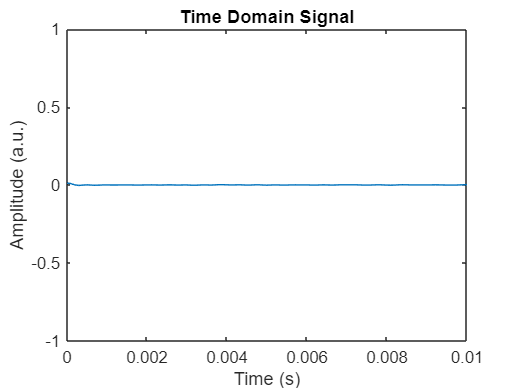

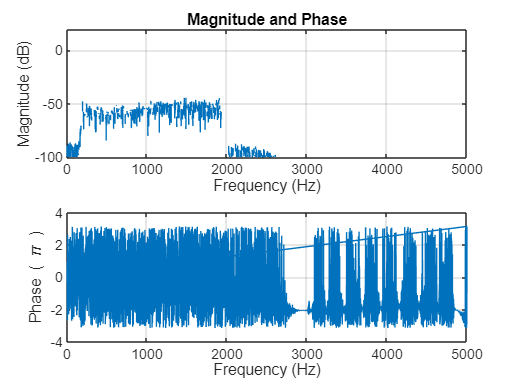

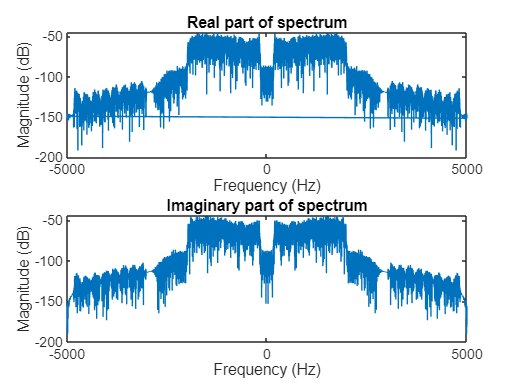

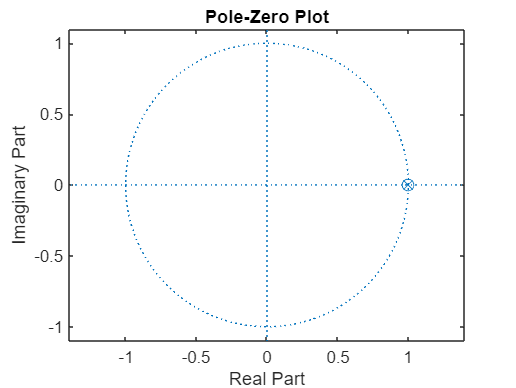

if strcmp(params.chosen_signal,'generate')
    [signal,t]=generate_signal1(params.generator_fs, params.generated_signal_duration, params.generated_signal_type, params.tone_freq, params.periodicity);
Fs=params.generator_fs;
end
if strcmp(params.chosen_signal,'wav')
filePath = 'animal_call.wav';
[signal, Fs] = audioread(filePath);
signal=resample(signal,params.target_fs,Fs);
Fs=params.target_fs;
t=0:1/Fs:length(signal)*(1/Fs)-(1/Fs);
end
[DFT_Y, f_DFT, STFT_Y, STFT_f, STFT_t]=frequency_analyser(signal, params, 40);
plotting(signal, t, 1, 1, DFT_Y, f_DFT, STFT_Y, STFT_t, STFT_f, params)

## Storing data as ASCII and plots as pdf

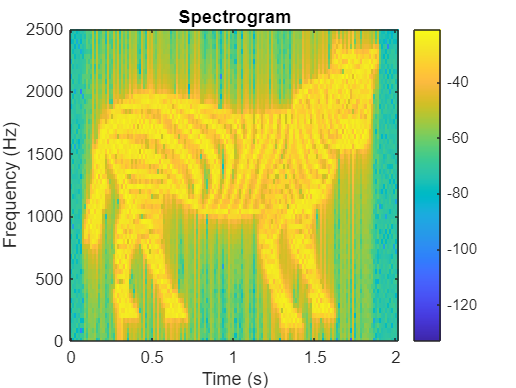

% Example: Filter Coefficients
b = [0.1, 0.15, 0.5, 0.15, 0.1];  % Example filter coefficients (numerator)
a = [1, -0.8];                   % Example filter coefficients (denominator)

% Save numerator coefficients
save('numerator_coefficients.txt', 'b', '-ascii');

% Save denominator coefficients
save('denominator_coefficients.txt', 'a', '-ascii');

% Save as a PDF with minimal white space
exportgraphics(gcf, 'filter_response.pdf', 'ContentType', 'vector', 'BackgroundColor', 'none');